% JSD Analysis

%algs = ["iTAML", "RPSnet", "DGR", "foster", "memo", "der"];
algs = ["iTAML", "RPSnet", "DGR", "foster"];
dataset = 'mnist';

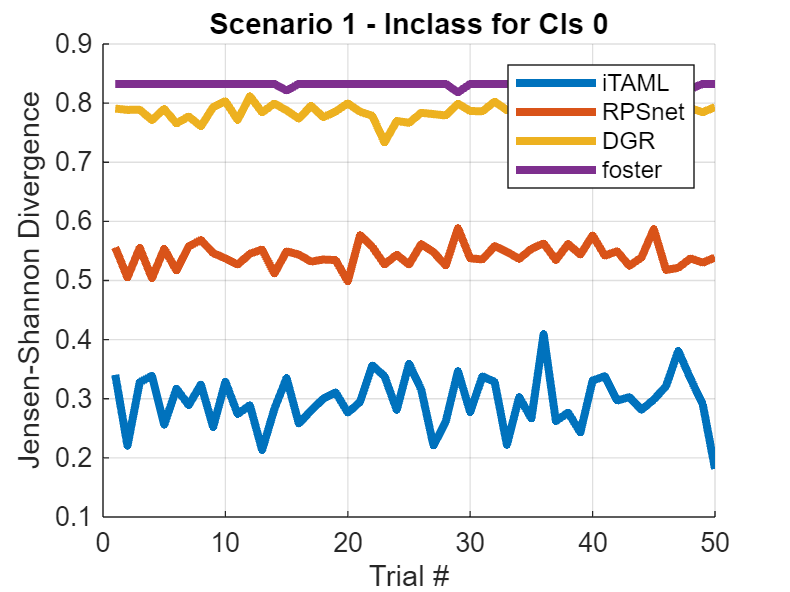

scn1_avgs =[];
scn1_stds = [];
scn2_avgs =[];
scn2_stds = [];

for j=1:length(algs)
    jsd_struct = load(sprintf("%s\\%s\\inclass_jsd.mat", algs(j), dataset));
    scn1_jsds = [];
    scn2_jsds = [];
    
    for i=1:length(fieldnames(jsd_struct))
        scn1_jsds = [scn1_jsds; getfield(jsd_struct, sprintf('t%d', i)).scn1];
        scn2_jsds = [scn2_jsds; getfield(jsd_struct, sprintf('t%d', i)).scn2];
    end

    % Plot JSDs
    figure(1)
    hold on;
    plot(1:50, scn1_jsds, 'LineWidth', 3)
    title('Scenario 1 - Inclass for Cls 0');
    xlabel('Trial #');
    ylabel('Jensen-Shannon Divergence');
    grid on;
    
    figure(2)
    hold on;
    plot(1:50, scn2_jsds, 'LineWidth', 3)
    title('Scenario 2 - Inclass for Cls 1');
    xlabel('Trial #');
    ylabel('Jensen-Shannon Divergence');
    grid on;

    % Calculate Averages and Std Devs
    scn1_avgs = [scn1_avgs; mean(scn1_jsds)];
    scn1_stds = [scn1_stds; std(scn1_jsds)];

    scn2_avgs = [scn2_avgs; mean(scn2_jsds)];
    scn2_stds = [scn2_stds; std(scn2_jsds)];
end

figure(1)
legend(algs);
hold off;

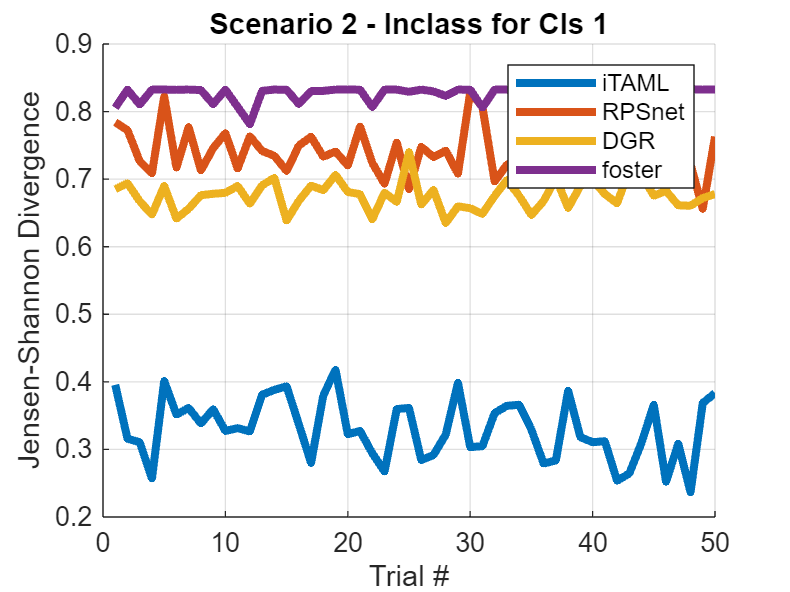


figure(2)
legend(algs);
hold off;

% Create Table
scn1_table = table(scn1_avgs, scn1_stds, ...
    'VariableNames', ["Avg", "Std Dev"], 'RowNames', algs)

scn1_table = 4×2 table
                Avg       Std Dev 
              _______    _________

    iTAML     0.29743     0.045132
    RPSnet    0.54245     0.019849
    DGR       0.78113     0.015419
    foster    0.83166    0.0028785


scn2_table = table(scn2_avgs, scn2_stds, ...
    'VariableNames', ["Avg", "Std Dev"], 'RowNames', algs)

scn2_table = 4×2 table
                Avg      Std Dev 
              _______    ________

    iTAML      0.3308    0.045322
    RPSnet    0.73849    0.033802
    DGR        0.6757    0.021142
    foster    0.82596    0.011603


% Create JSD Table
%{
row_names = [];
for i=1:length(fieldnames(jsd_struct))
    row_names = [row_names; sprintf("Trial %d", i)];
end
scns = ["scn1", "scn2", "scn3", "scn4"];
jsd_table = table(scn1_jsds, scn2_jsds, ...
    'VariableNames', ["Scn 1", "Scn 2"], 'RowNames', row_names)
%}